## Goal: Simulate an HIV Infection

Initial Parameters

clc;clear all; close all
times = linspace(0, 15, 1501);
% cells = [Healthy Infected Virus] for each time point
z0 = [1e6; 0; 100;]; % initialize initial values


### Simulate

[t, z] = ode45(@(t, z) simulate_infection(t, z), times, z0);

### Plot

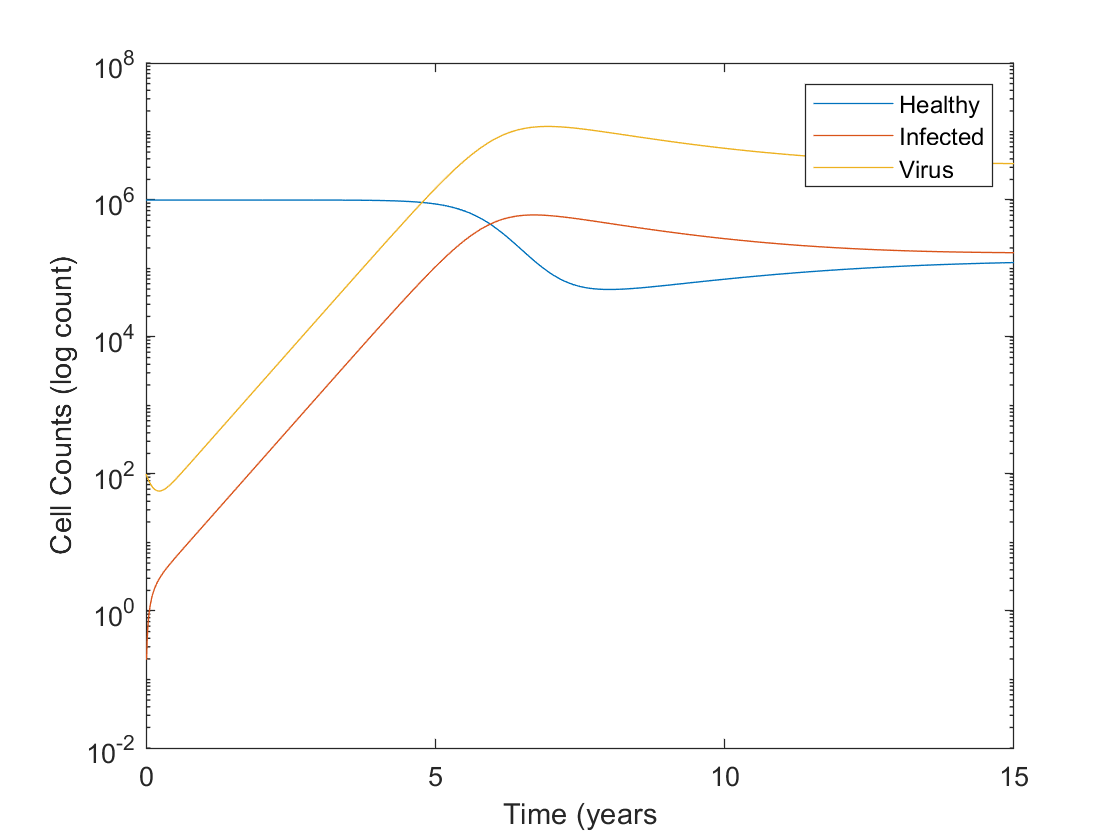

title('Simulated Virus')
h = semilogy(t, z(:, 1));
hold on;
i = semilogy(t, z(:, 2));
hold on;
v = semilogy(t, z(:, 3));
xlabel('Time (years')
ylabel('Cell Counts (log count)')
legend({'Healthy', 'Infected', 'Virus'})

function dzdt = simulate_infection(t, z)
% Values at a given moment
H = z(1);
I = z(2);
V = z(3);

% parameters
kr1 = 1e5; % new healthy cells per year
kr2 = 0.1; % death rate of healthy cells
kr3 = 2e-7; % healthy cells converting to infected cells
kr4 = 0.5; % death rate of infected cells
kr5 = 5; % death rate of virus
kr6 = 100; % production of virus by infected cells

% Calculate derivatives
dHdt = kr1 - kr2 * H - kr3 * H * V;
dIdt = kr3 * H * V - kr4 * I;
dVdt = - kr3 * H * V - kr5 * V + kr6 * I;

% return column vector
dzdt = [dHdt; dIdt; dVdt];
end
